# Solving Stokes' Equations

clear, clc
set_demo_defaults();

### Variable Viscosity Stokes Equation

Many geological materials experience ductile creep over long timescales, for example the earth mantle, glaciers and rock salt. To first-order these materials can be approximated as a very viscous fluid and modeled by the Stokes equation. The viscosity in these materials often varies by orders of magnitude due to temperature and dependence on deformation itself. Therefore, we are interested in the Stokes equation with variable viscosity, given by the balance of momentum and mass

1) $\nabla\cdot\left[\mu\left(\nabla\mathbf{v}+\nabla^T\mathbf{v})\right]-\nabla p=\mathbf{f}_1$ (momentum)

2)                                $\nabla\cdot\mathbf{v}=\mathbf{f}_2$ (mass)

where $\mathbf{v}
$, $p$ and $\mu
$ are the velocity, pressure and viscosity of the creeping solid and $\mathbf{f}_1$and $\mathbf{f}_2$ are source terms. Here we need to solve simultaneously for both the unkown velocity and pressure.

### Vector of unknowns and discrete linear system

As before we use the stagered grid with the pressure in the cell centers and the velocities on the cell faces.

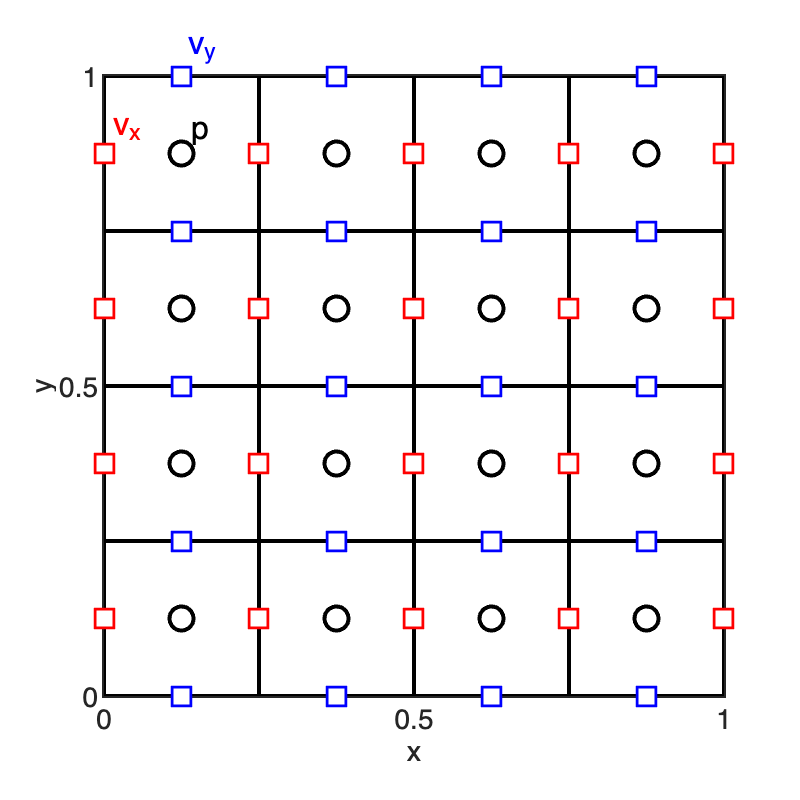

Gridp.xmin = 0; Gridp.xmax = 1; Gridp.Nx = 4;
Gridp.ymin = 0; Gridp.ymax = 1; Gridp.Ny = 4;
Grid = build_stokes_grid(Gridp);

figure('position',[10 10 400 400])
plot_unknowns(Grid.p)

We choose to order the vector of unknown as follows $\mathbf{u}^T = [\mathbf{v}_x^T,\, \mathbf{v}_y^T,\,\mathbf{p}]$ or combining the velocities as $\mathbf{u}^T = [\mathbf{v}^T,\,\mathbf{p}^T]$. Because the Stokes equations is linear in these unnowns we expect to write the discrete system as a linear system of equations

`Lu = f`

Here the system latrix `L` takes the from of a block matrix


$$\mathbf{L} =\pmatrix{\mathbf{A} & -\mathbf{G} \cr \mathbf{D} & \mathbf{O}}$$


where `D` and `G` are the standard discrete divergence and gradient operators on the stagered grid. The discrete system is then

`Av - Gp = f`$_1$

`Dv      = f`$_2$

The matrix `A` is new and discretizes the divergence of the deviatoric stress tensor. The deviatoric stress tensor is given by


$$\mathbf{\tau}=\mu\pmatrix{v_{x,x} & (v_{x,y}+v_{y,x})/2\cr (v_{x,y}+v_{y,x})/2 & v_{y,y}}$$


so that we need to evaluate the derivatives of both the velocity components in the x and y directions. From the locations of the velocity components on the grid, we see that

- $v_{x,x}$ and $v_{y,y}$ are naturally evaluated at the cell **centers**

- $v_{x,y}$ and $v_{y,x}$ are naturally evaluated at the cell **corners**

These velocity derivatives are most easily evaluated by introducing additional staggered grids as explained below.

### Staggered grid for Stokes equations

To facilitate the computation of the velocity derivatives we introduce two additional grids centered on the two velocity components. We refer to the girds by the variable in the cell center, so tht the standard grid shown above is the **pressure grid**. In 2D we have the following three grids:

- Pressure Grid is size Nx by Ny and is the primary grid used for mass balance and all subsequent transport computations/

- X-velocity Grid is size (Nx+1) by Ny and shifted by $\Delta x/2$ in the $x$ direction. It is used to compute the derivatives of the $x$-velocity component, $v_x$.

- Y-velocity Grid is size Nx by (Ny+1) and shifted by $\Delta y/2$ in the $y$ direction. It is used to compute the derivatives of the $y$-velocity component, $v_x$.

All three grids are shown in the figure below.

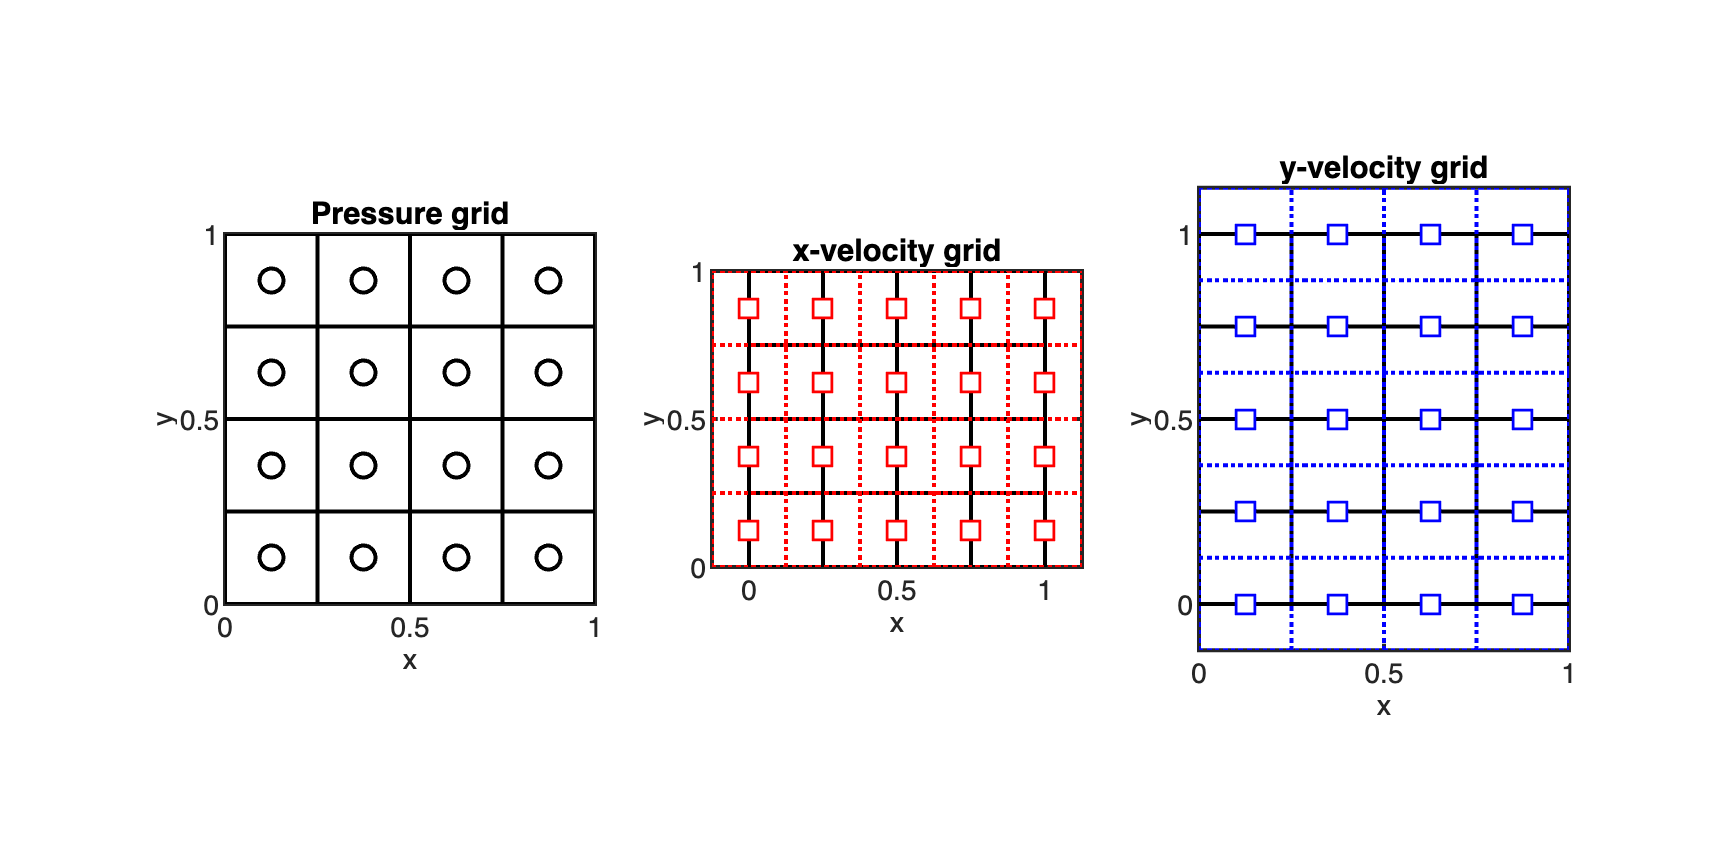

Gridp.xmin = 0; Gridp.xmax = 1; Gridp.Nx = 4;
Gridp.ymin = 0; Gridp.ymax = 1; Gridp.Ny = 4;
Grid = build_stokes_grid(Gridp);

figure('position',[10 10 1200 600])
subplot 131
plot_pressure_grid(Grid.p); 

subplot 132
plot_xvelocity_grid(Grid)

subplot 133
plot_yvelocity_grid(Grid)

### Discrete Stokes Operators

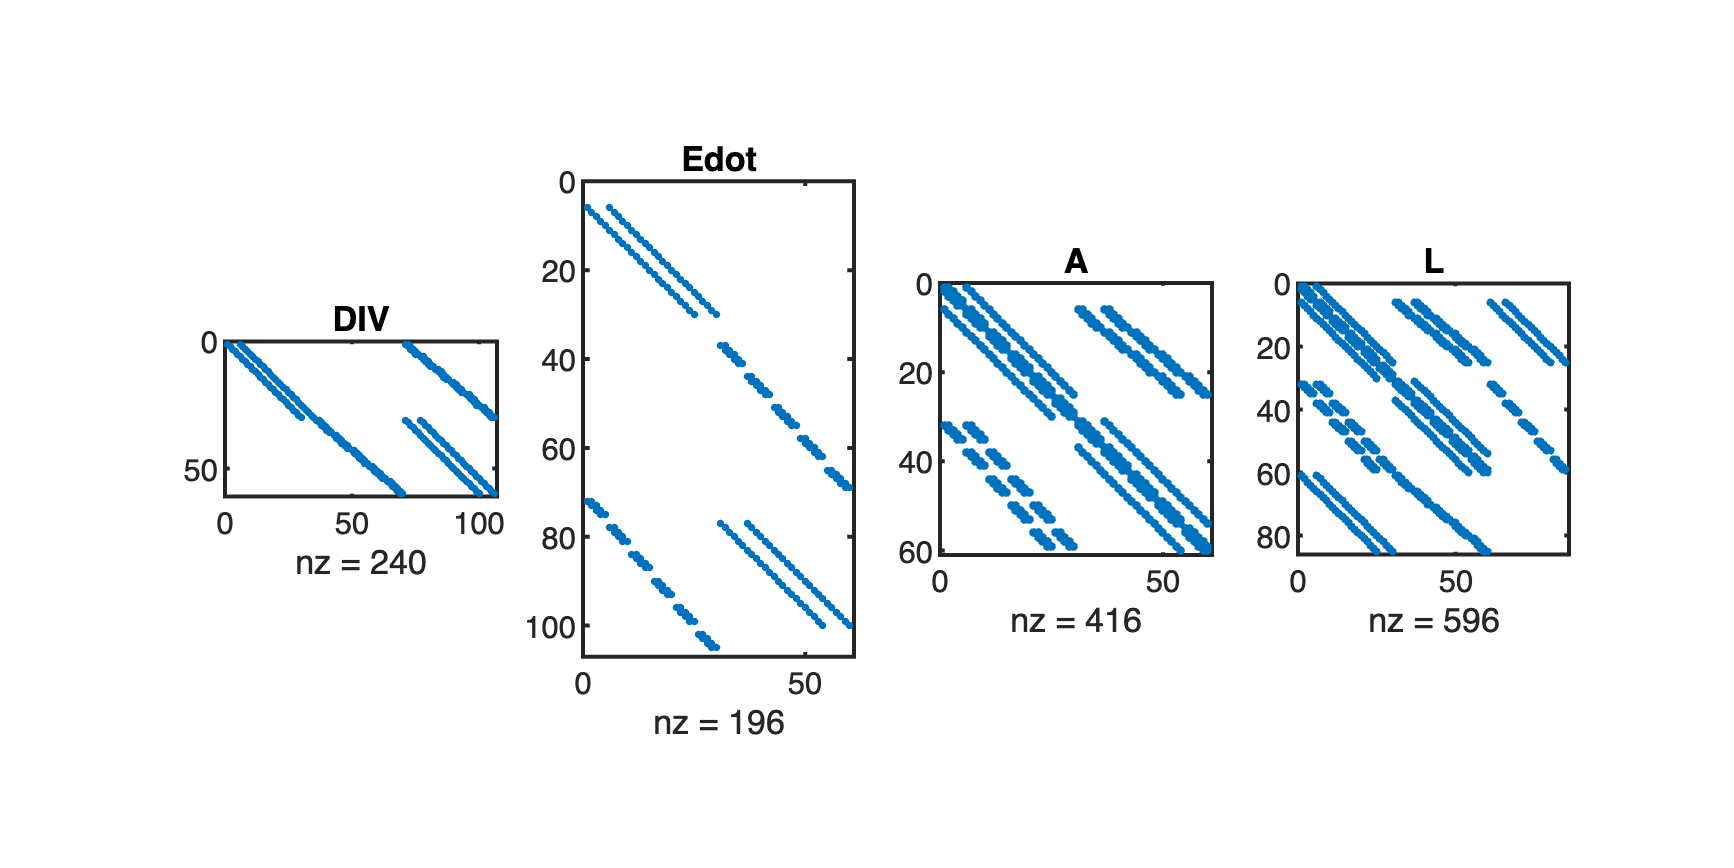

mu = 1; % viscosity - value does not matter here

% Definition of pressure grid
Gridp.xmin = 0; Gridp.xmax = 1; Gridp.Nx = 5;
Gridp.ymin = 0; Gridp.ymax = 1; Gridp.Ny = 5;

Grid = build_stokes_grid(Gridp);
[DIV,Edot,Dp,Gp,Z,I] = build_stokes_ops(Grid);

A = 2*mu*DIV*Edot; % 
L = [A, -Gp;...
     Dp, Z];

figure('position',[10 10 1200 600])
subplot 141
spy(DIV), title 'DIV'
subplot 142
spy(Edot), title 'Edot'
subplot 143
spy(A), title 'A'
subplot 144
spy(L), title 'L'

#### Symmetry of A

If the matrix `A` is symmetric the entire block system `L` is symmetric. To test for symmetry we check if `A'-A = 0`.

norm(full(A'-A))

ans = 0

We conclude that `A` is not symmetric. The reason it is not symmetric are the natural boundary conditions in `G` with break the symmetry with `D`. If we don't set the gradient on the boundary to zero `A` and `L` are symmetric. 

figure('position',[10 10 1200 600])
subplot 221
spy(A), title 'A (natural bc)'
subplot 222
spy(L), title 'L (natural bc)'

Grid.bc = 'none';
[D,Edot,Dp,Gp,Z,I] = build_stokes_ops_sym(Grid);
A = 2*mu*D*Edot; 
L = [A, -Gp;...
     Dp, Z];

norm(full(A'-A))

ans = 0

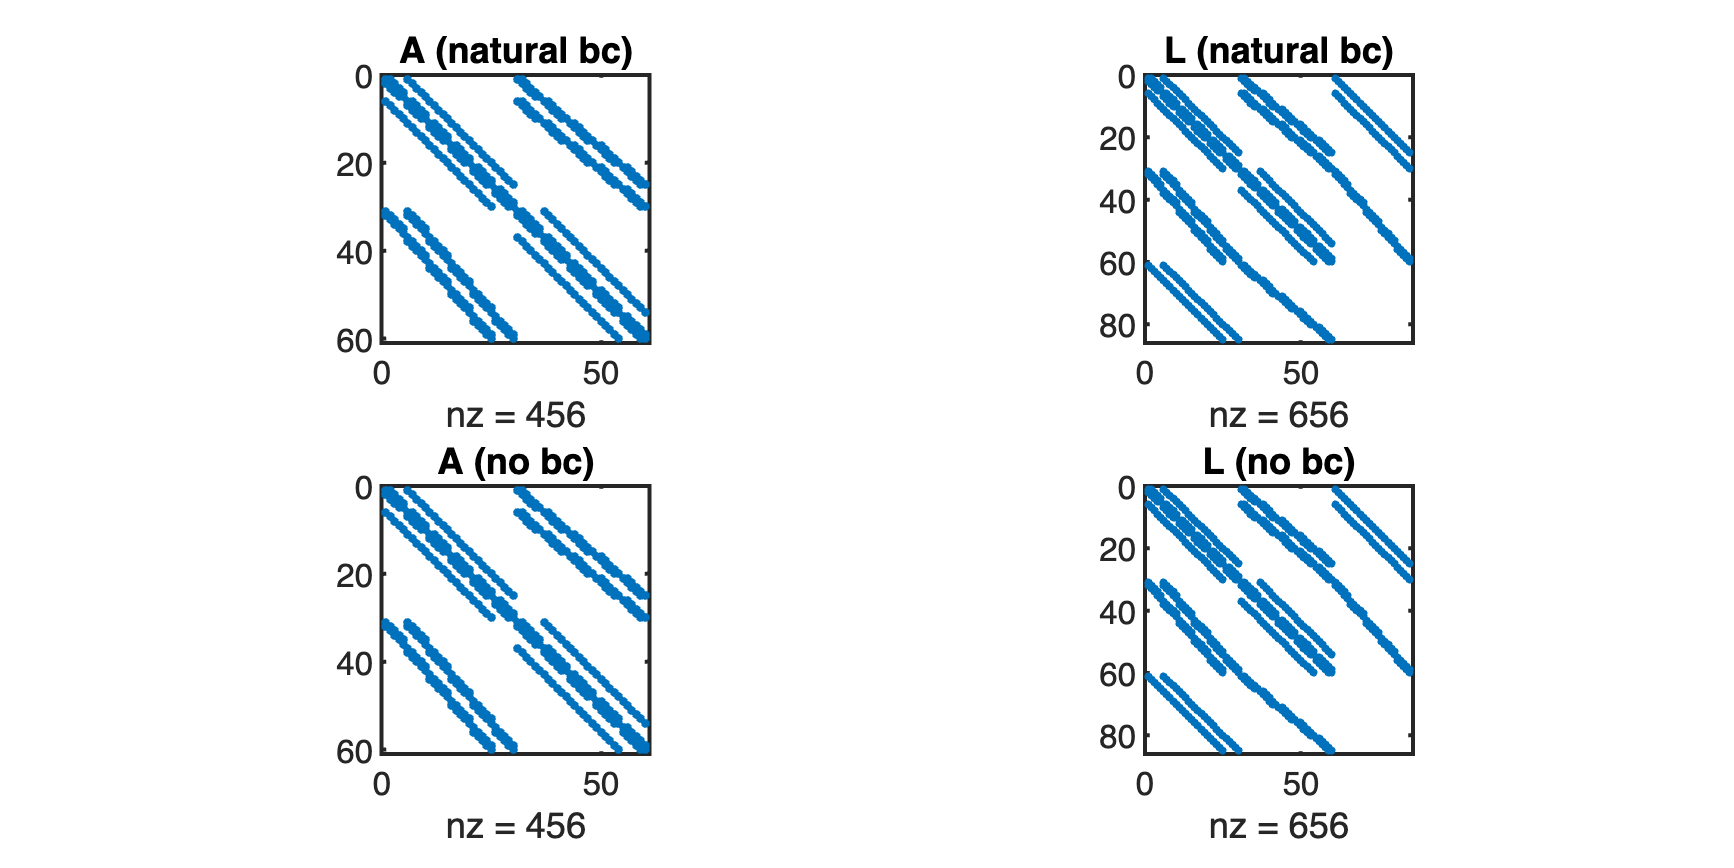

subplot 223
spy(A), title 'A (no bc)'
subplot 224
spy(L), title 'L (no bc)'

# Auxillary functions

% Plot unknowns

function [] = plot_unknowns(Grid)
% author: Marc Hesse
% date: 15 Apr 2020
% Description: Plots staggered grid with unknowns
x = Grid.xf; y = Grid.yf; Nx = Grid.Nx+1; Ny = Grid.Ny+1;
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
[Xx,Yx] = meshgrid(Grid.xf,Grid.yc);
[Xy,Yy] = meshgrid(Grid.xc,Grid.yf);

plot([x';x'],[zeros(1,Nx);ones(1,Nx)],'k-'), hold on
plot([zeros(1,Ny);ones(1,Ny)],[y';y'],'k-')
plot(Xc,Yc,'ko')
plot(Xx,Yx,'s','markerfacecolor','w','markeredgecolor','r')
plot(Xy,Yy,'s','markerfacecolor','w','markeredgecolor','b')
set(gca,'xtick',[0,.5,1],'ytick',[0,.5,1],'fontsize',14)
xlim([-.25 1.25])
ylim([-.25 1.25])
xlabel('x','fontsize',14)
ylabel('y','fontsize',14)
text(.14,.92,'p','fontsize',16,'color','k')
text(.01,.92,'v_x','fontsize',16,'color','r')
text(.13,1.05,'v_y','fontsize',16,'color','b')
axis equal tight
end

%% Plot pressure grid
function [] = plot_pressure_grid(Grid)
% author: Marc Hesse
% date: 15 Apr 2020
% Description: Plots staggered grid with unknowns
x = Grid.xf; y = Grid.yf; Nx = Grid.Nx+1; Ny = Grid.Ny+1;
[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
[Xx,Yx] = meshgrid(Grid.xf,Grid.yc);
[Xy,Yy] = meshgrid(Grid.xc,Grid.yf);

plot([x';x'],[zeros(1,Nx);ones(1,Nx)],'k-'), hold on
plot([zeros(1,Ny);ones(1,Ny)],[y';y'],'k-')
plot(Xc,Yc,'ko')
% plot(Xx,Yx,'rs','markerfacecolor','w')
% plot(Xy,Yy,'bs','markerfacecolor','w')
set(gca,'xtick',[0,.5,1],'ytick',[0,.5,1],'fontsize',14)
xlim([-.25 1.25])
ylim([-.25 1.25])
xlabel('x','fontsize',14)
ylabel('y','fontsize',14)
axis equal tight
title 'Pressure grid'
end


%% Plot x-velocity grid
function [] = plot_xvelocity_grid(Grid)
% author: Marc Hesse
% date: 15 Apr 2020
% Description: Plots staggered grid with unknowns

% Pressure grid
x = Grid.p.xf; y = Grid.p.yf; Nx = Grid.p.Nx+1; Ny = Grid.p.Ny+1;
[Xc,Yc] = meshgrid(Grid.p.xc,Grid.p.yc);
[Xx,Yx] = meshgrid(Grid.p.xf,Grid.p.yc);
[Xy,Yy] = meshgrid(Grid.p.xc,Grid.p.yf);

plot([x';x'],[zeros(1,Nx);ones(1,Nx)],'k-'), hold on
plot([zeros(1,Ny);ones(1,Ny)],[y';y'],'k-')
plot(Xx,Yx,'s','markerfacecolor','w','markeredgecolor','r')

% x-velocity grid
x = Grid.x.xf; y = Grid.x.yf; Nx = Grid.x.Nx+1; Ny = Grid.x.Ny+1;
[Xc,Yc] = meshgrid(Grid.x.xc,Grid.x.yc);
[Xx,Yx] = meshgrid(Grid.x.xf,Grid.x.yc);
[Xy,Yy] = meshgrid(Grid.x.xc,Grid.x.yf);

plot([x';x'],[Grid.x.ymin*ones(1,Nx);Grid.x.ymax*ones(1,Nx)],'r:'), hold on
plot([Grid.x.xmin*ones(1,Ny);Grid.x.xmax*ones(1,Ny)],[y';y'],'r:')
set(gca,'xtick',[0,.5,1],'ytick',[0,.5,1],'fontsize',14)
xlim([-.25 1.25])
ylim([-.25 1.25])
xlabel('x','fontsize',14)
ylabel('y','fontsize',14)
axis equal tight
title 'x-velocity grid'
end

%% Plot y-velocity grid
function [] = plot_yvelocity_grid(Grid)
% author: Marc Hesse
% date: 15 Apr 2020
% Description: Plots staggered grid with unknowns

% Pressure grid
x = Grid.p.xf; y = Grid.p.yf; Nx = Grid.p.Nx+1; Ny = Grid.p.Ny+1;
[Xc,Yc] = meshgrid(Grid.p.xc,Grid.p.yc);
[Xx,Yx] = meshgrid(Grid.p.xf,Grid.p.yc);
[Xy,Yy] = meshgrid(Grid.p.xc,Grid.p.yf);

plot([x';x'],[zeros(1,Nx);ones(1,Nx)],'k-'), hold on
plot([zeros(1,Ny);ones(1,Ny)],[y';y'],'k-')
plot(Xy,Yy,'s','markerfacecolor','w','markeredgecolor','b')

% y-velocity grid
x = Grid.y.xf; y = Grid.y.yf; Nx = Grid.y.Nx+1; Ny = Grid.y.Ny+1;
[Xc,Yc] = meshgrid(Grid.y.xc,Grid.y.yc);
[Xx,Yx] = meshgrid(Grid.y.xf,Grid.y.yc);
[Xy,Yy] = meshgrid(Grid.y.xc,Grid.y.yf);

plot([x';x'],[Grid.y.ymin*ones(1,Nx);Grid.y.ymax*ones(1,Nx)],'b:'), hold on
plot([Grid.y.xmin*ones(1,Ny);Grid.y.xmax*ones(1,Ny)],[y';y'],'b:')
set(gca,'xtick',[0,.5,1],'ytick',[0,.5,1],'fontsize',14)
xlim([-.25 1.25])
ylim([-.25 1.25])
xlabel('x','fontsize',14)
ylabel('y','fontsize',14)
axis equal tight
title 'y-velocity grid'
end
